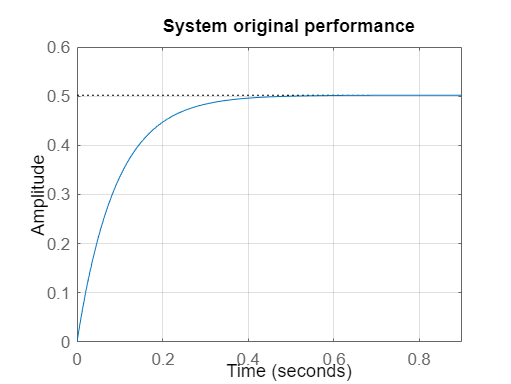

s=tf('s');
OL= 1.008/(0.1816*s+1);
OCL= 1.008/(0.1816*s+2.008);
% System original performance
step(OCL)
grid
title('System original performance');

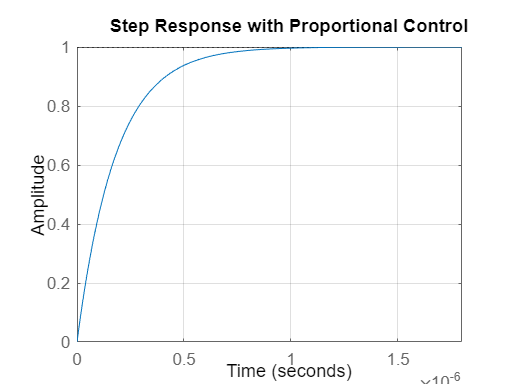

% Proportional controller
Kp = 1000000;
sys_P = feedback(Kp*OL,1);
step(sys_P)
grid
title('Step Response with Proportional Control')

% Proportional Integral controller
Kpi = 3;
a2 = 14/3;
Ki = Kpi*a2

Ki = 14

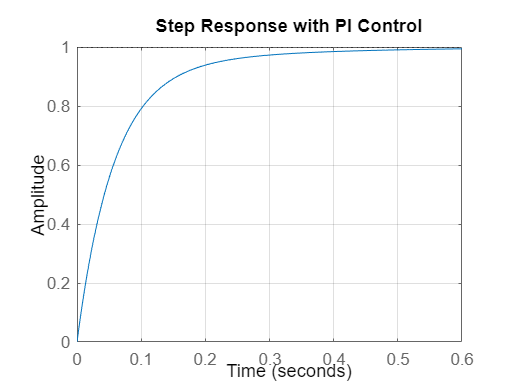

sys_PIcl = feedback(Kpi*(s+a2)*OL/s,1);
step(sys_PIcl)
grid
title('Step Response with PI Control')

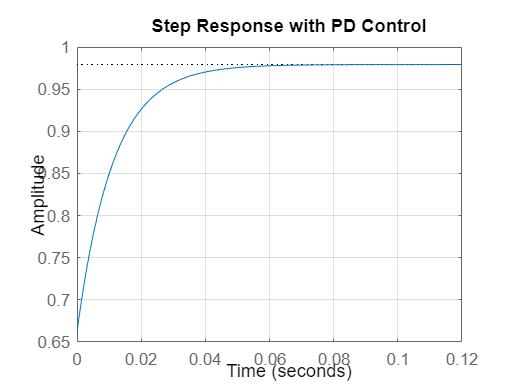

% Proportional Derivative controller
Kpd = 0.3528;
sys_PDcl = feedback(Kpd*(s+132.24)*OL,1);
step(sys_PDcl)
grid
title('Step Response with PD Control')

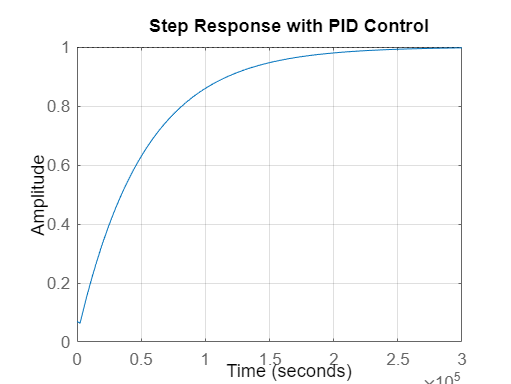

% PID controller
Kpid = 0.0135;
sys_PIDcl = feedback(Kpid*(s+1.4569)*(s+0.001)*OL/s,1);
step(sys_PIDcl)
grid
title('Step Response with PID Control')

sys_bac2=tf(tf2.Numerator,tf2.Denominator)

sys_bac2 =
 
          46.56
  ---------------------
  s^2 + 7.856 s + 46.55
 
Continuous-time transfer function.



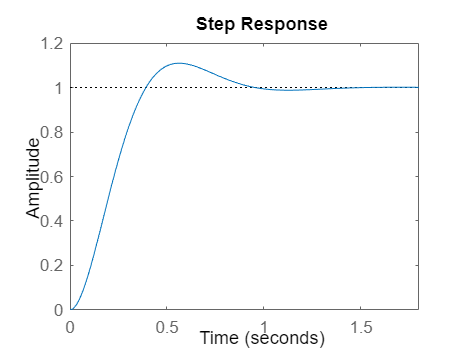

step(sys_bac2)